clear all;
close all;

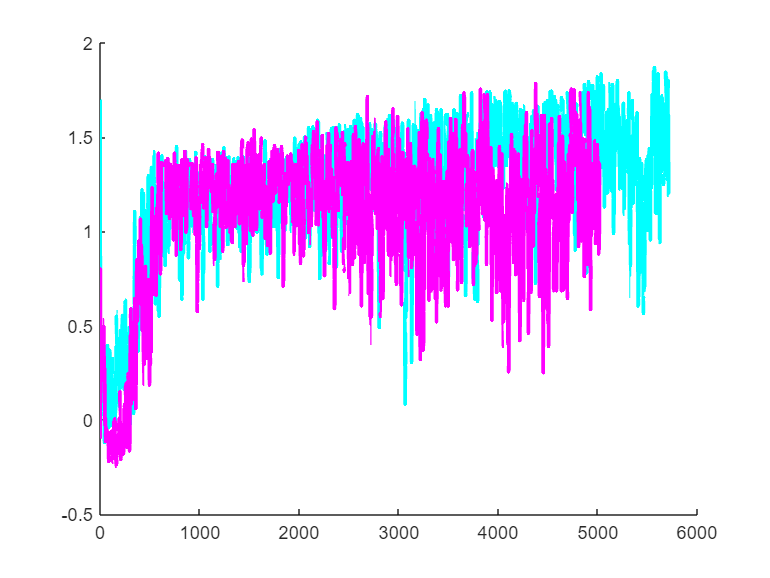


% convergence example of learning

a1 = load("DQN/savedParameters/Env4_myNet2_LearnRate00005_Entropy09_test.mat");
a2 = load("DQN/savedParameters/Env4_myNet2_LearnRate0001_Entropy09_test.mat");
a2 = load("DQN/savedParameters/Env4_myNet_LearnRate00005_Entropy09_test.mat");


figure;
hold on;
plot(a1.episode_index, a1.average_reward, 'c', 'LineWidth', 2, 'DisplayName', '0.2');
plot(a2.episode_index, a2.average_reward, 'm', 'LineWidth', 2, 'DisplayName', '0.2');

hold off;

Comparison of the 4 basic environments for different exploration policies.

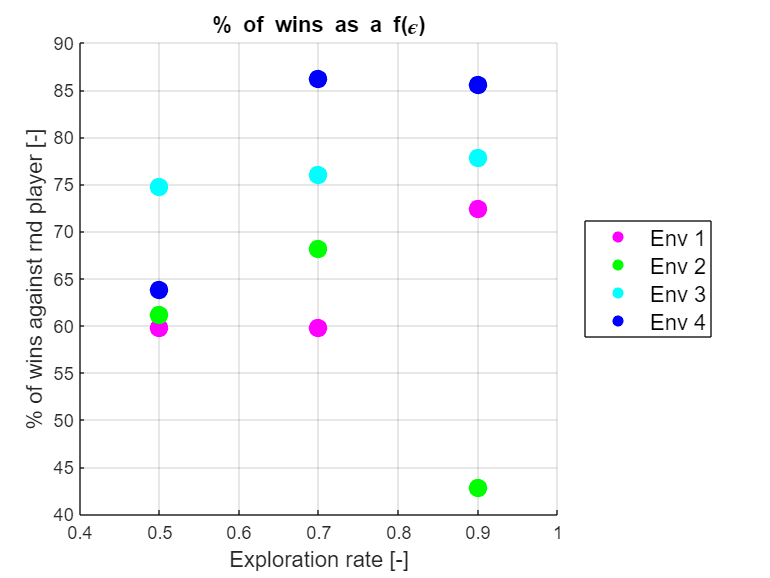


% Plot 4 environments

x_axis_epsilon= [0.5, 0.7, 0.9];
env1_wins_rnd= [59.8, 59.8, 72.4];
env2_wins_rnd= [61.2, 68.2, 42.8];
env3_wins_rnd= [74.8, 76, 77.8];
env4_wins_rnd= [ 63.8, 86.2, 85.6];

figure
hold on;
scatter(x_axis_epsilon, env1_wins_rnd, 100, "magenta", "filled")
scatter(x_axis_epsilon, env2_wins_rnd, 100, "green", "filled")
scatter(x_axis_epsilon, env3_wins_rnd, 100, "cyan", "filled")
scatter(x_axis_epsilon, env4_wins_rnd, 100, "blue", "filled")
xlim([0.4, 1])
legend('Env 1', 'Env 2', 'Env 3', 'Env 4')

% Move the legend to the side
lgd = legend('Env 1', 'Env 2', 'Env 3', 'Env 4', 'FontSize', 12);
lgd.Location = 'eastoutside';

xlabel('Exploration rate [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins as a f(\epsilon)', 'FontSize', 12)
grid on
hold off

Effect of the learning rate on Env 4 and Env 3.

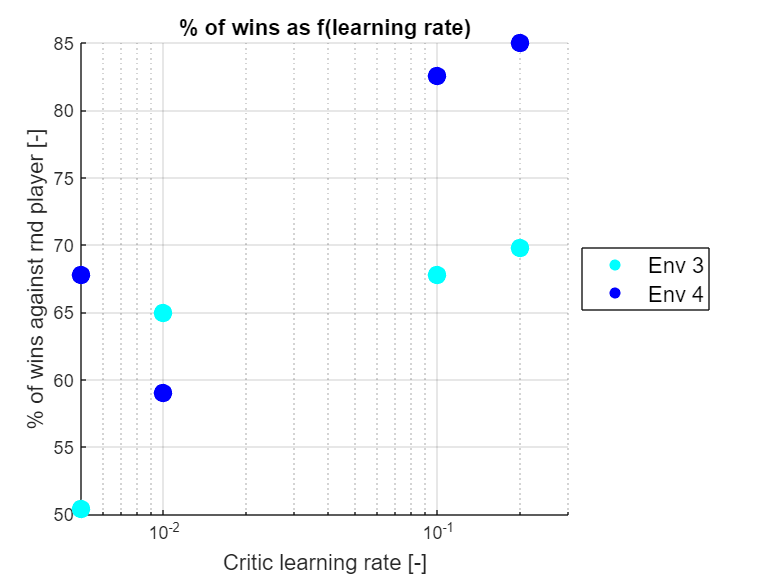

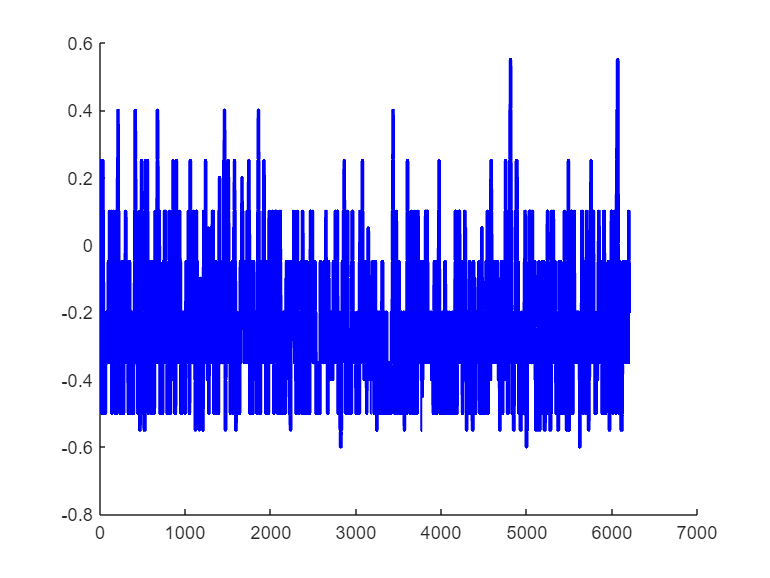


% Plot 3 and 4 environments

x_axis_learn_rate= [0.005, 0.01, 0.1, 0.2];
env3_wins_rnd= [50.4, 65.0, 67.8, 69.8];
env4_wins_rnd= [ 67.8, 59, 82.6, 85.0];

figure
hold on;
scatter(x_axis_learn_rate, env3_wins_rnd, 100, "cyan", "filled")
scatter(x_axis_learn_rate, env4_wins_rnd, 100, "blue", "filled")
xlim([0, 0.3])
legend('Env 3', 'Env 4')
% Set the x-axis to log scale
set(gca, 'XScale', 'log')

% Move the legend to the side
lgd = legend('Env 3', 'Env 4', 'FontSize', 12);
lgd.Location = 'eastoutside';

xlabel('Critic learning rate [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins as f(learning rate)', 'FontSize', 12)
grid on
hold off

Effect of the mini batch size on Env 4

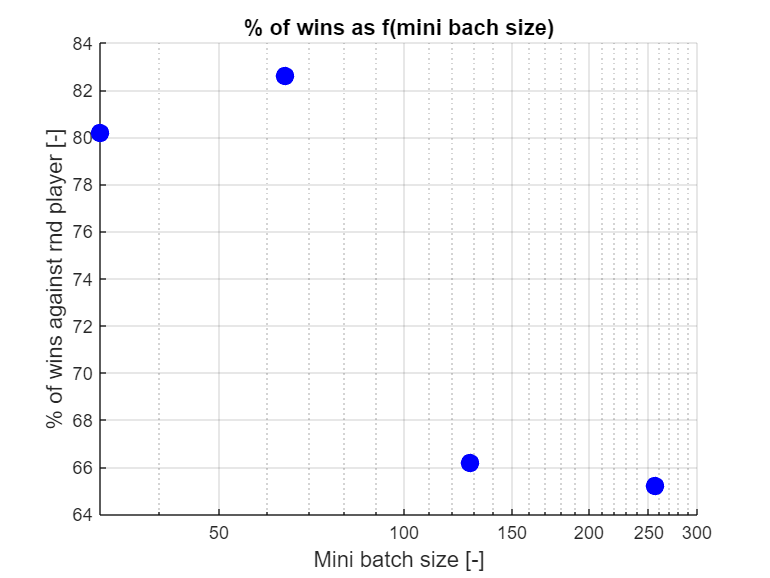

% Plot 3 and 4 environments

x_axis_batch_size= [32, 64, 128, 256];
env4_wins_rnd= [80.2, 82.6, 66.2, 65.2];

figure
hold on;
scatter(x_axis_batch_size, env4_wins_rnd, 100, "blue", "filled")
xlim([0, 300])
% legend('Env 3', 'Env 4')
% Set the x-axis to log scale
set(gca, 'XScale', 'log')

% Move the legend to the side
% lgd = legend('Env 3', 'Env 4', 'FontSize', 12);
% lgd.Location = 'eastoutside';

xlabel('Mini batch size [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins as f(mini bach size)', 'FontSize', 12)
grid on
hold off

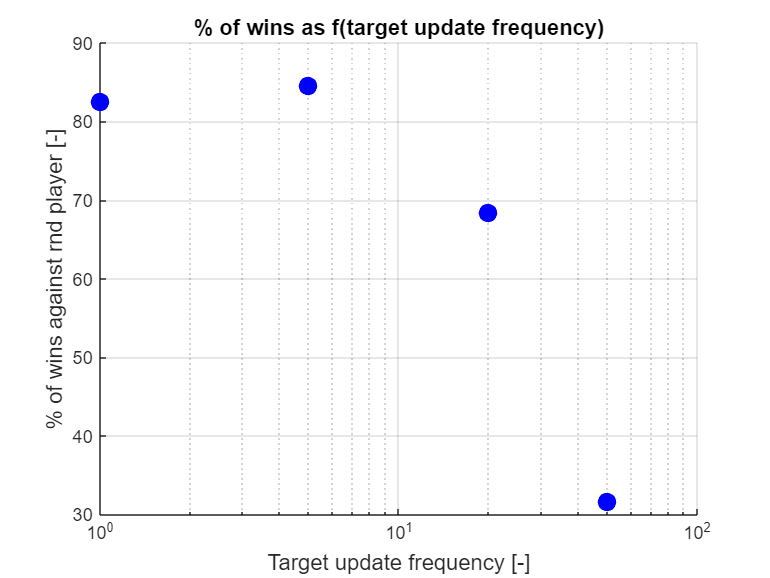

% Plot env 4 for Freq Update

x_axis_freq= [1, 5, 20, 50];
env4_wins_rnd= [82.6, 84.6, 68.4, 31.6];

figure
hold on;
scatter(x_axis_freq, env4_wins_rnd, 100, "blue", "filled")
% xlim([0, 0.3])
% legend('Env 3', 'Env 4')
% Set the x-axis to log scale
set(gca, 'XScale', 'log')

% Move the legend to the side
% lgd = legend('Env 3', 'Env 4', 'FontSize', 12);
% lgd.Location = 'eastoutside';

xlabel('Target update frequency [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins as f(target update frequency)', 'FontSize', 12)
grid on
hold off

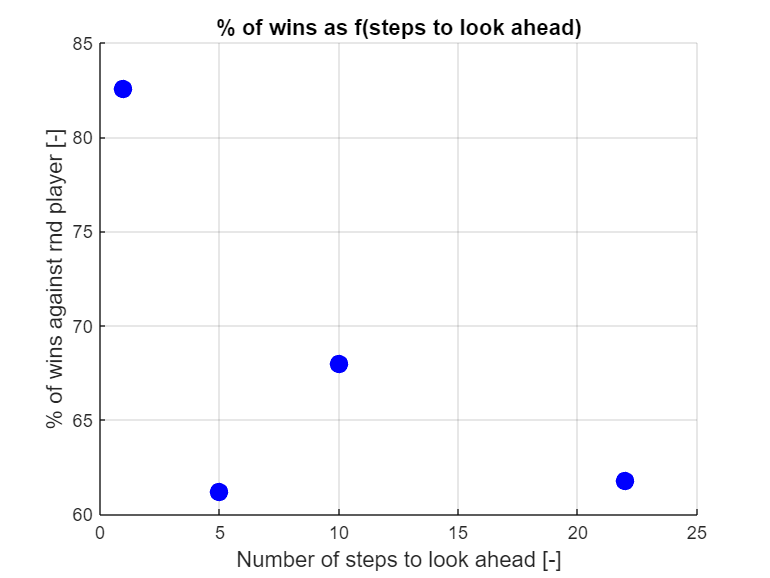

% Plot env 4 for NumStepsToLookAhead

x_axis_freq= [1, 5, 10, 22];
env4_wins_rnd= [82.6, 61.2, 68, 61.8];

figure
hold on;
scatter(x_axis_freq, env4_wins_rnd, 100, "blue", "filled")
% xlim([0, 0.3])
% legend('Env 3', 'Env 4')
% Set the x-axis to log scale
% set(gca, 'XScale', 'log')

% Move the legend to the side
% lgd = legend('Env 3', 'Env 4', 'FontSize', 12);
% lgd.Location = 'eastoutside';

xlabel('Number of steps to look ahead [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins as f(steps to look ahead)', 'FontSize', 12)
grid on
hold off

% Plot env 4 for Discount factor

x_axis_freq= [1e-3, 2e-3, 1e-2];
env4_wins_rnd= [82.6, 88.8, 82.4];

figure
hold on;
scatter(x_axis_freq, env4_wins_rnd, 100, "blue", "filled")
xlim([0, 1])
% legend('Env 3', 'Env 4')
% Set the x-axis to log scale
% set(gca, 'XScale', 'log')

% Move the legend to the side
% lgd = legend('Env 3', 'Env 4', 'FontSize', 12);
% lgd.Location = 'eastoutside';

xlabel('Discount factor [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins as f(discount factor)', 'FontSize', 12)
grid on
hold off

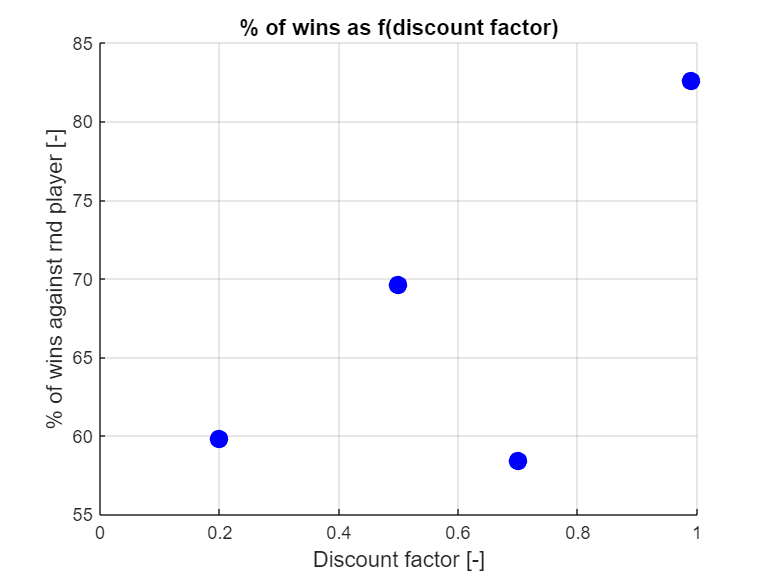


% Plot env 4 for Discount factor

x_axis_freq= [0.2, 0.5, 0.7, 0.99];
env4_wins_rnd= [59.8, 69.6, 58.4, 82.6];

figure
hold on;
scatter(x_axis_freq, env4_wins_rnd, 100, "blue", "filled")
xlim([0, 1])
% legend('Env 3', 'Env 4')
% Set the x-axis to log scale
% set(gca, 'XScale', 'log')

% Move the legend to the side
% lgd = legend('Env 3', 'Env 4', 'FontSize', 12);
% lgd.Location = 'eastoutside';

xlabel('Discount factor [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins as f(discount factor)', 'FontSize', 12)
grid on
hold off

Comparison of the 3 featured environments for different exploration policies.

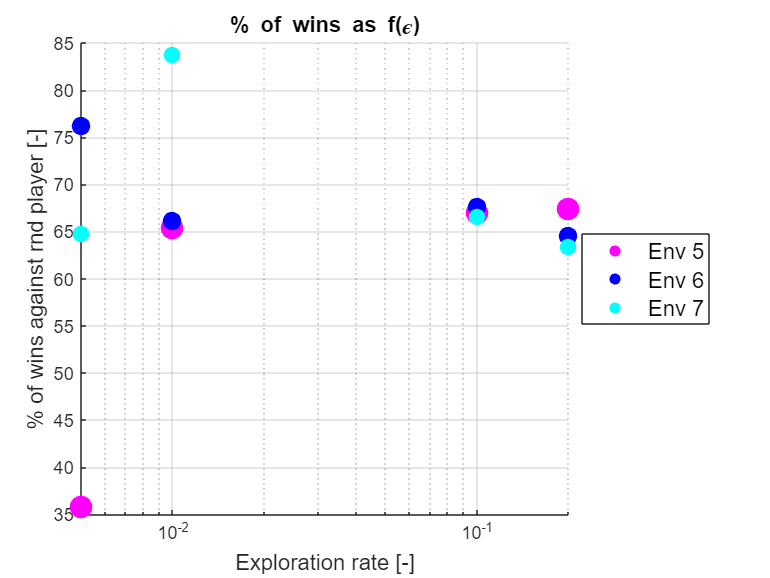


% Plot 3 featured environments

x_axis_learn= [0.005, 0.01, 0.1, 0.2];
env5_wins_rnd= [35.8, 65.4, 67.0, 67.4];
env6_wins_rnd= [76.2, 66.2, 67.6, 64.6];
env7_wins_rnd= [64.8, 83.8, 66.6, 63.4];


figure
hold on;
scatter(x_axis_learn, env5_wins_rnd, 150, "magenta", "filled")
scatter(x_axis_learn, env6_wins_rnd, 100, "blue", "filled")
scatter(x_axis_learn, env7_wins_rnd, 80, "cyan", "filled")

legend('Env 5', 'Env 6', 'Env 7')

% Move the legend to the side
lgd = legend('Env 5', 'Env 6', 'Env 7', 'FontSize', 12);
lgd.Location = 'eastoutside';

% Set the x-axis to log scale
set(gca, 'XScale', 'log')

xlabel('Exploration rate [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins as f(\epsilon)', 'FontSize', 12)
grid on
hold off

Comparison of the 3 featured environments for different exploration policies.

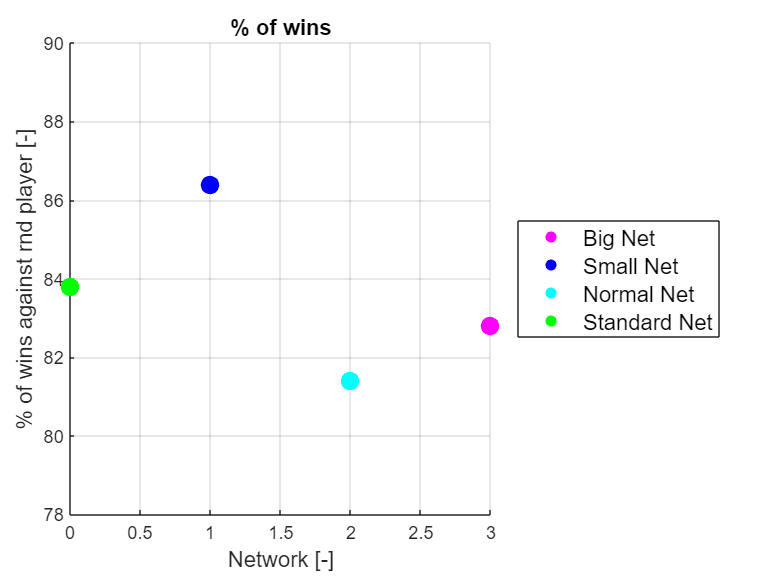


% Plot Neural networks featured environments

x_axis= [0, 1, 2, 3];
big_Net_env7_wins_rnd= [0,0,0,82.8];
small_Net_env7_wins_rnd= [0, 86.4, 0, 0];
my_Net_env7_wins_rnd= [0, 0, 81.4, 0];
std_env7_wins_rnd=[83.8, 0, 0, 0];

figure
hold on;
scatter(x_axis, big_Net_env7_wins_rnd, 100, "magenta", "filled")
scatter(x_axis, small_Net_env7_wins_rnd, 100, "blue", "filled")
scatter(x_axis, my_Net_env7_wins_rnd, 100, "cyan", "filled")
scatter(x_axis, std_env7_wins_rnd, 100, "green", "filled")
ylim([78, 90])
legend('Big Net', 'Small Net', 'Normal Net', 'Standard Net')

% Move the legend to the side
lgd = legend('Big Net', 'Small Net', 'Normal Net', 'Standard Net', 'FontSize', 12);
lgd.Location = 'eastoutside';

% % Set the x-axis to log scale
% set(gca, 'XScale', 'log')

xlabel('Network [-]', 'FontSize', 12)
ylabel('% of wins against rnd player [-]', 'FontSize', 12)
title('% of wins', 'FontSize', 12)
grid on
hold off

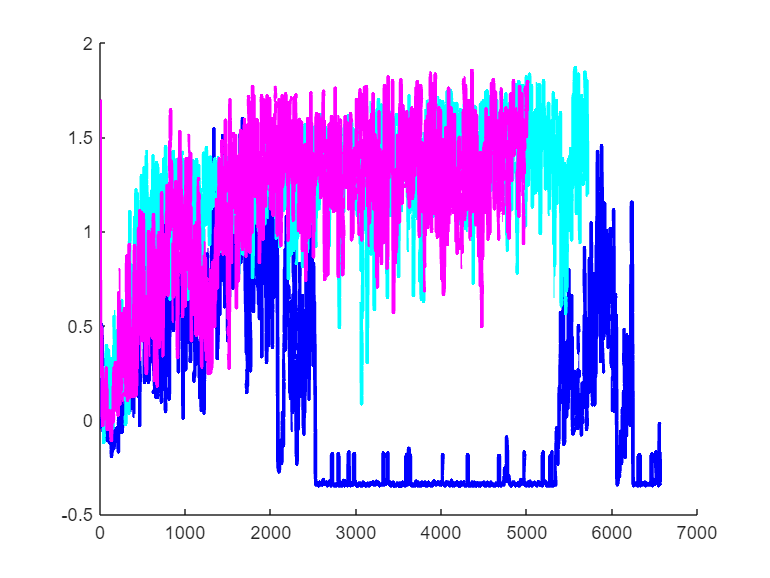



% convergence example of learning

big_Net_env7_wins_rnd = load("DQN/savedParameters/Env7_bigNet_LearnRate001_Entropy09.mat");
small_Net_env7_wins_rnd = load("DQN/savedParameters/Env7_smallNet_LearnRate001_Entropy09.mat");
my_Net_env7_wins_rnd = load("DQN/savedParameters/Env7_myNet_LearnRate001_Entropy09.mat");

aaa = load("DQN/savedParameters/Env4_myNet2_LearnRate00005_Entropy09_test.mat");
aaa2 = load("DQN/savedParameters/Env4_myNet2_LearnRate0001_Entropy09_test.mat");


figure;
hold on;
plot(big_Net_env7_wins_rnd.episode_index, big_Net_env7_wins_rnd.average_reward, 'b', 'LineWidth', 2, 'DisplayName', '0.2');
% plot(small_Net_env7_wins_rnd.episode_index, small_Net_env7_wins_rnd.average_reward, 'y', 'LineWidth', 2, 'DisplayName', '0.2');
% plot(my_Net_env7_wins_rnd.episode_index, my_Net_env7_wins_rnd.average_reward, 'm', 'LineWidth', 2, 'DisplayName', '0.2');
% plot(env3_0005.episode_index, env3_0005.average_reward, 'c', 'LineWidth', 2, 'DisplayName', '0.2');
plot(aaa.episode_index, aaa.average_reward, 'c', 'LineWidth', 2, 'DisplayName', '0.2');
plot(aaa2.episode_index, aaa2.average_reward, 'm', 'LineWidth', 2, 'DisplayName', '0.2');

hold off;